Data Processing for the SHARC-I Buoy IMU

IMUData = readtable('05Hz_20mm_irreg.csv');
X_acc = IMUData{:, 2};
Y_acc = IMUData{:, 3};
Z_acc = IMUData{:, 4};
roll = IMUData{:, 5};
pitch = IMUData{:, 6};
yaw = IMUData{:, 7};

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = height(IMUData(:, 4));             % Length of signal
t = (0:L-1)*T;        % Time vector


**X-Axis**


%X_acc calculations
X_acc_ms2 = X_acc/16381.0; 

X_velocity_uncalibrated = cumtrapz(X_acc_ms2);

X_position_uncalibrated = cumtrapz(X_velocity_uncalibrated);

X_acc_ms2_calibrated = (detrend(X_acc_ms2))/(1669.316);

X_velocity_calibrated = cumtrapz(X_acc_ms2_calibrated);

X_position_calibrated = cumtrapz(X_velocity_calibrated);

**Y-Axis**


%Y_acc calculations
Y_acc_ms2 = Y_acc/16381.0; 

Y_velocity_uncalibrated = cumtrapz(Y_acc_ms2);

Y_position_uncalibrated = cumtrapz(Y_velocity_uncalibrated);

Y_acc_ms2_calibrated = (Y_acc + 42.729)/(1668.9);

Y_velocity_calibrated = cumtrapz(Y_acc_ms2_calibrated);

Y_position_calibrated = cumtrapz(Y_velocity_calibrated);




**Z-Axis **

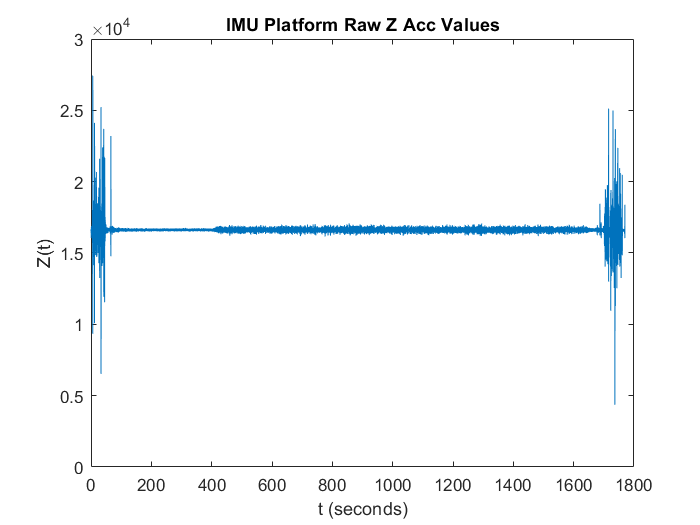


Z_acc_ms2 = Z_acc/16381.0; 

Z_acc_ms2_calibrated = ((Z_acc)-92.2236)/(1686.46) - 9.8172;

Z_acc_ms2_calibrated  = detrend(Z_acc_ms2_calibrated);

Z_acc_ms2_calibrated = lowpass(Z_acc_ms2_calibrated, 10, Fs);


t = t;

plot(t, Z_acc)
title('IMU Platform Raw Z Acc Values')
xlabel('t (seconds)')
ylabel('Z(t)')

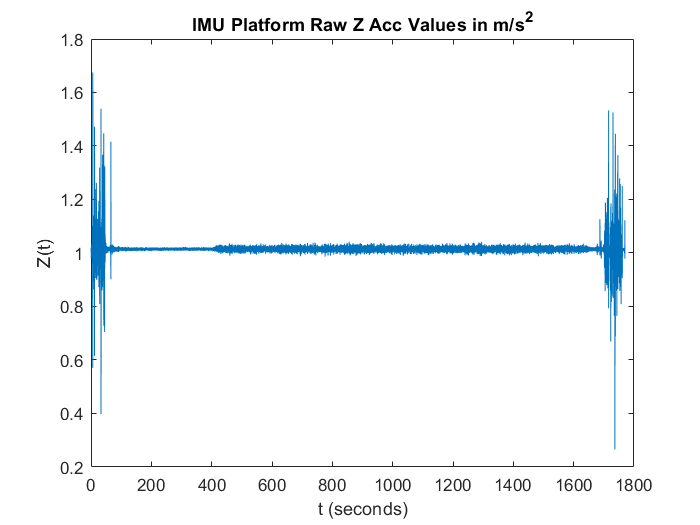


plot(t, Z_acc_ms2)
title('IMU Platform Raw Z Acc Values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

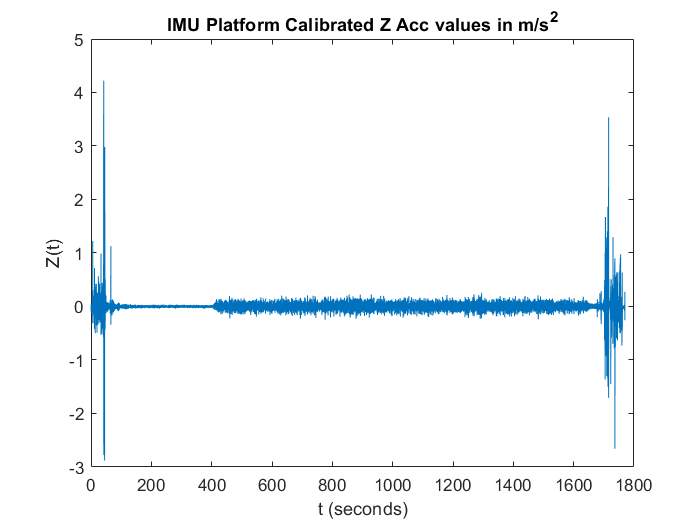


plot(t, Z_acc_ms2_calibrated)
title('IMU Platform Calibrated Z Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')




Z = fft(Z_acc_ms2_calibrated(2000:10000, 1))*Fs; %NB: Truncate to wave active periods before fft
L = length(Z);
P2 = abs(Z/L);
P1 = P2(1:L/2+1);

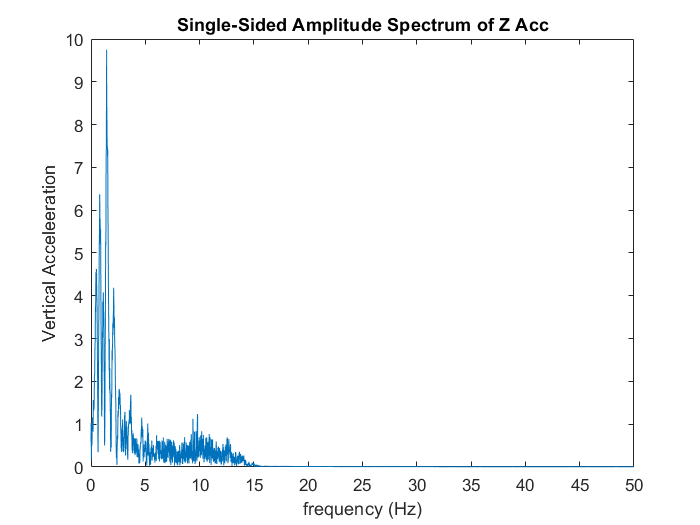

P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('frequency (Hz)')
ylabel('Vertical Acceleeration')

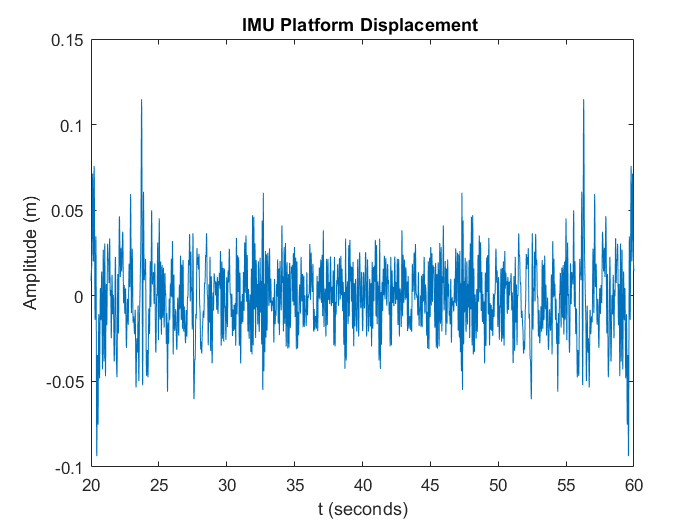





%%Wave Height Calculation
f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 100; %Nyquist Frequency

for i = 1:length(f)
    if f < f1 
        P2(i, 1) = 0;
    end
        if f > f1 & f < f2
            P2(i, 1) = (1/2)*(1-cos(pi*(f-f1)/(f2-f1))*(-1/(2*pi*f^2)))*P2(i, 1);
        end
            if f > f2 & f < fc
                P2(i, 1) = -1/(2*pi*f^2)*P1(i,1); 
            end
end


waveHeightIMU = ifft(P2)*1/(2*T);
t_trunc = (0:length(waveHeightIMU)-1)*T;
plot(t_trunc(1, 2000:6000), waveHeightIMU(2000:6000,1))
title('IMU Platform Displacement ')
xlabel('t (seconds)')
ylabel('Amplitude (m)')

**Pitch** 


%pitch = detrend(pitch);

pitch_dps = pitch/131.0; 

pitch_degrees_uncalibrated = cumtrapz(pitch_dps)/360;

pitch_dps_calibrated = (pitch-190.96)/137.32;

pitch_degrees_calibrated = cumtrapz(pitch_dps_calibrated)/360;


**Roll** 

%Roll Calculations
roll_dps = pitch/131.0; 

roll_degrees_uncalibrated = cumtrapz(roll_dps)/360;

roll_dps_calibrated = (roll-74.9)/131.226;

roll_degrees_calibrated = cumtrapz(roll_dps_calibrated)/360;


**Yaw**


%Yaw Calculations
yaw_dps = pitch/131.0; 

yaw_degrees_uncalibrated = cumtrapz(yaw_dps)/360;

yaw_dps_calibrated = (yaw-20.5908)/145.342;

yaw_degrees_calibrated = cumtrapz(yaw_dps_calibrated)/360;

